# Inside the black box

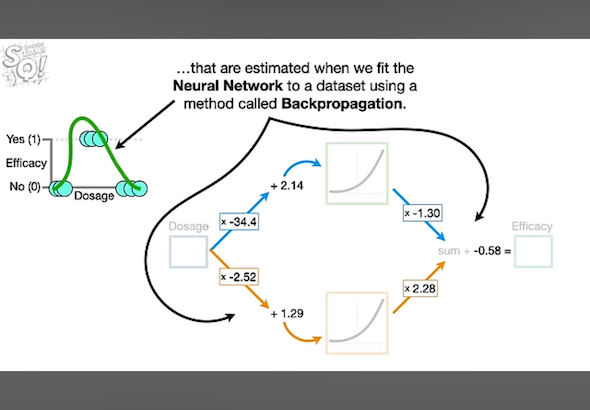

dosage = 0.5;
w = zeros(4,1);
w(1) = 3.34;
w(2) = -3.53;
w(3) = -1.22;
w(4) = -2.30;
b = zeros(3,1);
b(1) = -1.43;
b(2) =  0.57;
b(3) =  2.61;

getEff(dosage, w, b)

ans = 1.0010

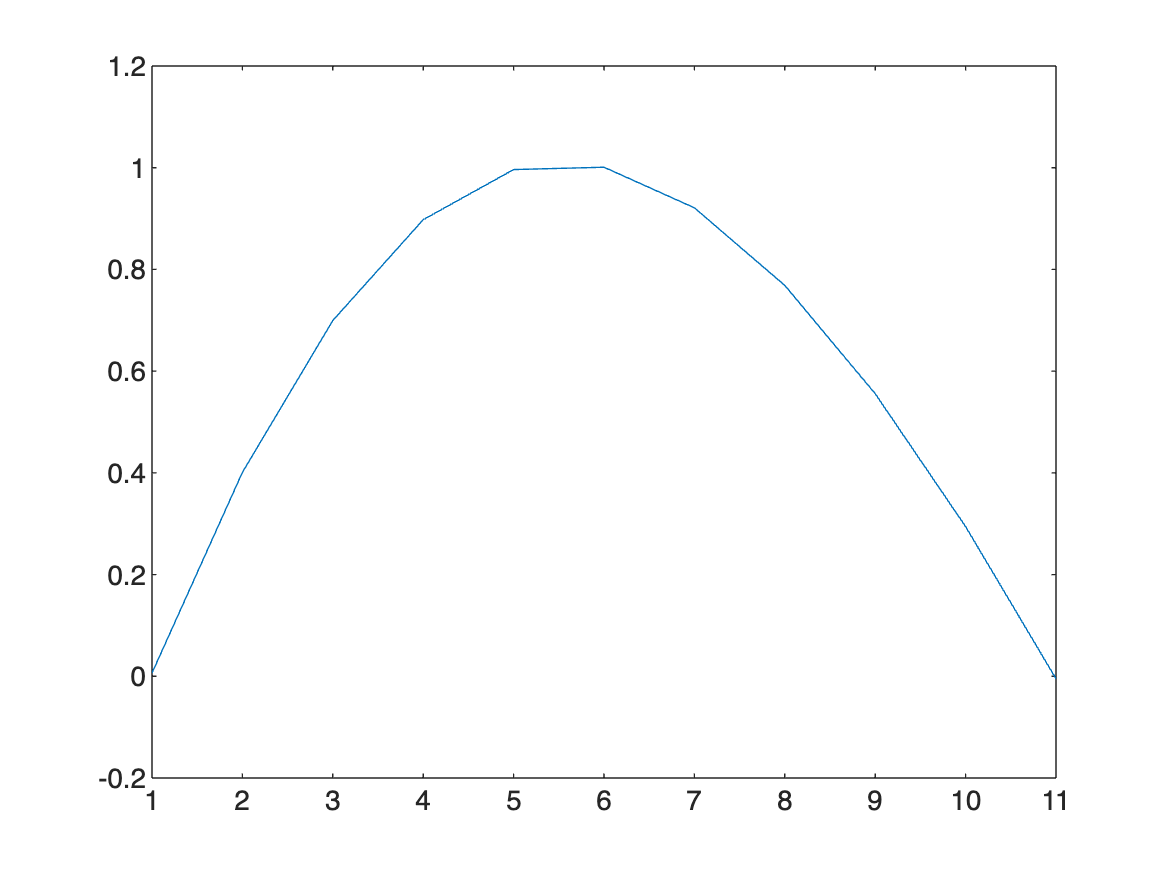

effGraph = getEff(0:0.1:1,w,b);
plot(effGraph)


function efficacy = getEff(dosage, w, b)
    xs = dosage .* w(1:2,:) + b(1:2,1);
    L1 = softplus(xs);
    blueOrange = L1 .* w(3:4,:);
    greenSquiggle = sum(blueOrange);
    efficacy = greenSquiggle + b(3);
end


## Activation Function

function act = softplus(xx)
    act = log(1+exp(xx));
end
